[pos, err, xyzt_guess] = tag_pair_min_z(dist_front_history, dist_back_history, p_tag_front, p_tag_back, anchor_mat)

pos =     0.9438    1.0518    0.9579    0.9440    1.0637    1.0247    1.0247    1.0277    1.0891    1.0648    0.9736    1.1475    1.1239    1.0140    1.1918    1.0852    1.1329    1.0205    1.1198    1.1141    1.0382    1.1234    1.1546    1.1410    1.1039    1.0560    0.9200    1.2402    1.1832    1.2511    1.3488    1.3833    1.3567    1.3765    1.6250    1.6419    1.6482    1.6054    1.6673    1.7977    1.8078    1.7558    1.7070    1.7336    1.7873    1.8506    1.7402    1.8230    1.8198    1.9023
    1.0131    0.8984    1.0321    0.8659    0.9056    1.0845    1.0762    1.0557    1.0110    0.9655    1.0573    0.9722    0.9391    1.0423    1.0946    1.0120    0.9575    1.1374    1.0669    1.0019    1.0985    1.0724    1.0102    0.9657    1.0336    0.9729    1.0706    1.0329    1.0697    1.1063    1.0186    0.9922    1.1000    1.1491    0.9740    0.9948    1.1306    1.0739    1.0516    1.0772    1.0070    1.0721    1.1011    1.1559    1.1325    1.0392    1.0651    0.9350    1.1095   

err =     0.0168
    0.0545
    0.0575
    0.0684
    0.0500
    0.0172
    0.0575
    0.0459
    0.0315
    0.0748


xyzt_guess =     0.9349    1.0274    0.9337    0.9457    1.0444    1.0310    1.0362    1.0169    1.0651    1.0530    0.9508    1.1365    1.1163    1.0067    1.2416    1.1067    1.1118    0.9353    1.1036    1.1159    1.0313    1.1242    1.1565    1.1473    1.1192    1.0450    0.9285    1.1999    1.2068    1.2608    1.3849    1.3617    1.3662    1.3439    1.6749    1.5983    1.6129    1.5598    1.6786    1.7569    1.8293    1.7734    1.7491    1.7570    1.7636    1.8762    1.7104    1.8235    1.8845    1.8595
    1.0021    0.8741    1.0029    0.8660    0.8869    1.0870    1.0783    1.0518    0.9868    0.9582    1.0332    0.9726    0.9336    1.0364    1.1475    1.0294    0.9370    1.0488    1.0516    1.0051    1.0930    1.0718    1.0150    0.9768    1.0489    0.9646    1.0840    0.9892    1.1012    1.1048    1.0537    0.9716    1.1140    1.1199    1.0173    0.9572    1.1027    1.0377    1.0631    1.0427    1.0233    1.0907    1.1303    1.1761    1.1133    1.0578    1.0366    0.9377    1.

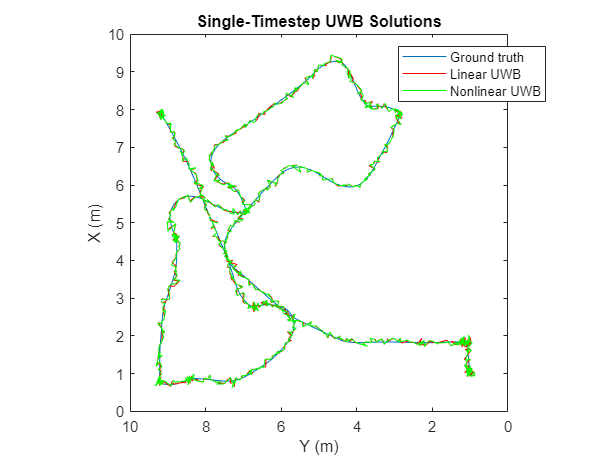


plot(robot_state_history(1,:), robot_state_history(2,:)); hold on
plot(pos(1,:), pos(2,:), 'r'); 
plot(xyzt_guess(1,:), xyzt_guess(2,:), 'g'); hold off
axis square
view(-90,90);
xlabel("X (m)")
ylabel("Y (m)")
title("Single-Timestep UWB Solutions")

legend(["Ground truth", "Linear UWB", "Nonlinear UWB"], "Location","northeast")

rms(vecnorm(pos([1 2],:) - robot_state_history(1:2,:))) * 1e2

ans = 8.0566

rms(vecnorm(xyzt_guess([1 2],:) - robot_state_history(1:2,:))) *  1e2

ans = 8.6135


rms(wrapToPi(vecnorm(pos([1 2],:) - robot_state_history(1:2,:))))

ans = 0.0806

rms(wrapToPi(xyzt_guess([3],:) - robot_state_history(3,:)))

ans = 1.6342

function a = rms(x)
a = sqrt(mean(x.^2));
end